tableN = readtable("si_anode.csv");
cVecN = table2array(tableN(:,"capacity"));
vVecN = table2array(tableN(:,"voltage"));

[thetaVecN, vThetaVecN] = normalizeCapacity(cVecN, vVecN);

tablePNMC = readtable("nmc_cathode.csv");
cVecP = table2array(tablePNMC(:,"capacity"));
vVecP = table2array(tablePNMC(:,"voltage"));

[thetaVecP, vThetaVecP] = normalizeCapacity(cVecP, vVecP);

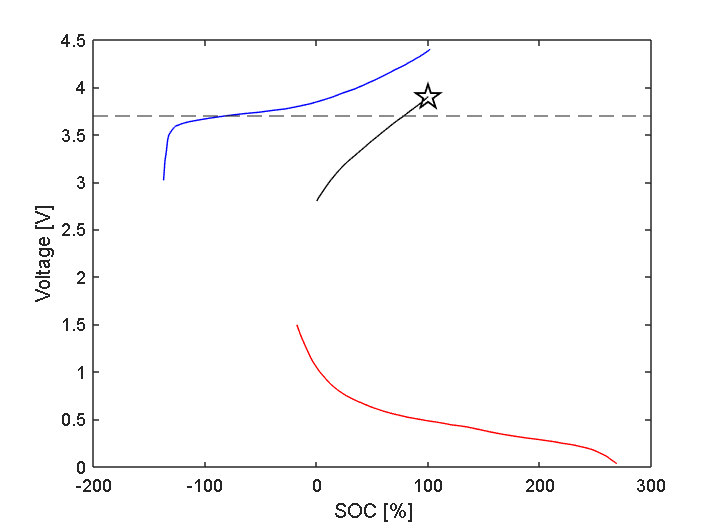

% To construct lowest possible voltage at 100 % SOC, assume 1.5x anode excess
x0 = 0;
y0 = 0.5;
cP = 3.45; % mAh/cm^2, from BOL model
cN = cP*1.2; % mAh/cm^2, assuming no anode excess
vMin = 2.8;
vMax = 3.9;
chargeDir = "dchg";
linestyle = "-";

[cVecNModel, vVecNModel, cVecPModel, vVecPModel, cVecFullModel, vVecFullModel] = combineHalfCells( ...
    thetaVecN, vThetaVecN, thetaVecP, vThetaVecP, cN, cP, x0, y0, vMin, vMax, chargeDir);
figure(1)
SOCFull = 100 - cVecFullModel/max(cVecFullModel)*100;
SOCP = 100 - cVecPModel/max(cVecFullModel)*100;
SOCN = 100 - cVecNModel/max(cVecFullModel)*100;
plot(SOCFull, vVecFullModel, 'k', ...
    SOCP, vVecPModel, 'b', SOCN, ...
    vVecNModel, 'r')
    ylabel("Voltage [V]")
    xlabel("SOC [%]")
hold on
yline(3.7, "--")
plot(SOCFull(1), vVecFullModel(1), "kp", LineWidth=1, MarkerSize=14)
%xlim([0,100])
hold off